# Perturbed vs. Unperturbed Orbit Trajectory Propagation:

**Author:** Richard Vincent. DeMark

**University:** Embry-Riddle Aeronautical University

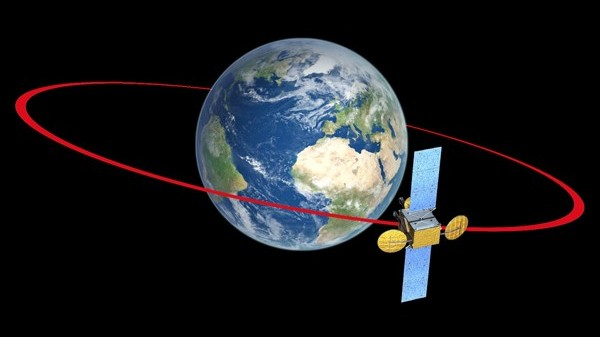

Image courtesy of [The European Space Agency](https://www.esa.int/ESA) (ESA)

This MATLAB LiveScript is designed to propagate any conic section orbit trajectory about a user-selected spherical celestial object within the solar system using Keplerian orbital mechanics. Using only initial postion and velocity state vectors, one can propagate circular, elliptical, parabolic, or hyperbolic orbits about an orbit body over time using a Cowell Method numerical integrator. I will be comparing the unperturbed two-body propagation with a purturbed propagated orbit due to orbit body spherical oblateness of the same initial state vectors. Once the orbit state vectors are obtained, I will then plot the orbit trajectories in three dimensions specific to the selected orbit body and see the differences in trajectories.

# User Selects an Orbital Body:

First, we must select an orbit body and initialize the orbital environmental parameters. I've restricted the user to use only the predefined solar system bodies. These solar system bodies include *Mercury, Venus, Earth, Mars, Jupiter, Saturn, Uranus, and Neptune*. We could easily implement additional orbital bodies with the assumption that the orbit body is spherical or very nearly spherical. When one selects an orbit body, its unique orbital environmental parameters(3) can be initialized. These parameters include its [gravitational parameter](https://en.wikipedia.org/wiki/Standard_gravitational_parameter) defined as $\mu =G\cdot M$ in units of $\frac{{\mathrm{km}}^3 }{s^2 }$ (which is its own constant), their respective masses ($M_{\mathrm{body}}$) in units of $\mathrm{kg}$, their distances from the Sun ($R_{\mathrm{sun}}$) in units of $\mathrm{km}$, and their equatorial radii ($R_{\mathrm{body}}$) in units of $\mathrm{km}$. For the case when we wish to perturb the orbit due to orbit body spherical oblateness, it is also necessary to include the orbit body zonal harmonic coefficients which represent differential gravity accross the surface or the orbit body. For example, the surface gravity at Mt. Everest will be different from the surface gravity on the shores of the Dead Sea (see **Figure 1**).

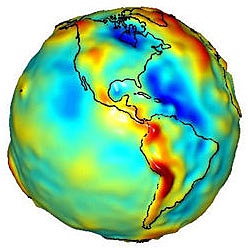

**Figure 1** - Variations in Earth's surface gravity (Image courtesy of [NASA](https://www.nasa.gov/audience/foreducators/k-4/features/F_Measuring_Gravity_With_Grace.html))

The differences in elevation on Earth mean that Earth's surface gravity is not constant. This will have decaying effects on our propagated orbit and can be observed over long enough time spans. I will use the MATLAB [Zonal Harmonic Gravity Model](https://www.mathworks.com/help/aeroblks/zonalharmonicgravitymodel.html) to obtain the required zonal harmonic coefficients ($J$) which are unitless. 

% clear all
clc,clear
% User must define the orbit body
% Select: 'Mercury','Venus','Earth','Mars','Jupiter','Saturn','Uranus','Neptune', or 'Pluto'
Orbit_Body = 'Earth'

Orbit_Body = 'Earth'

## Orbit Body Parameters:

% Associate proper orbital environmental parameters
switch Orbit_Body
    case 'Earth'
        u = 3.986004415e5; % km^3/s^2
        Body = 'Earth';
        map = imread('Images/Earth_map.jpg'); % read planet map
        %map = imread('/Documents/Fall 2019/Orbital Mechanics/OrbitDetermination/OrbitViz/viz2/Images/Earth_map.jpg');
        map = imrotate(map,180); % rotate upright
        Body_Radius = 6371; % km
        Body_Mass = 5.97219e24; % kg
        Dist_to_Sun = 149.6e6; % km
        J_num = [0;0.0010826269;-0.0000025323;-0.0000016204]; % zonal harmonic coefficients
    case 'Mercury'
        u = 2.2032e4; % km^3/s^2
        Body = 'Mercury';
        map = imread('Images/Mercury_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 2440; % km
        Body_Mass = 3.285e23; % kg
        Dist_to_Sun = 57.9e6; % km
        J_num = [0;0.00006]; % zonal harmonic coefficients
    case 'Venus'
        u = 3.257e5; % km^3/s^2
        Body = 'Venus';
        map = imread('Images/Venus_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 6052; % km
        Body_Mass = 4.867e24; % kg
        Dist_to_Sun = 108.2e6; % km
        J_num = [0;0.000027]; % zonal harmonic coefficients
    case 'Mars'
        u = 4.305e4; % km^3/s^2
        Body = 'Mars';
        map = imread('Images/Mars_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 3390; % km
        Body_Mass = 6.39e23; % kg
        Dist_to_Sun = 227.9e6; % km
        J_num = [0;0.001964;0.000036]; % zonal harmonic coefficients
    case 'Jupiter'
        u = 1.268e8; % km^3/s^2
        Body = 'Jupiter';
        map = imread('Images/Jupiter_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 69911; % km
        Body_Mass = 1.898e27; % kg
        Dist_to_Sun = 778.3e6; % km
        J_num = [0;0.01475;0;-0.00058]; % zonal harmonic coefficients
    case 'Saturn'
        u = 3.794e7; % km^3/s^2
        Body = 'Saturn';
        map = imread('Images/Saturn_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 58232; % km
        Body_Mass = 5.683e26; % kg
        Dist_to_Sun = 1427.0e6; % km
        J_num = [0;0.01645;0;-0.001]; % zonal harmonic coefficients
    case 'Uranus'
        u = 5.794e6; % km^3/s^2
        Body = 'Uranus';
        map = imread('Images/Uranus_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 25632; % km
        Body_Mass = 8.681e25; % kg
        Dist_to_Sun = 2871.0e6; % km
        J_num = [0;0.012]; % zonal harmonic coefficients
    case 'Neptune'
        u = 6.809e6; % km^3/s^2
        Body = 'Neptune';
        map = imread('Images/Neptune_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 24622; % km
        Body_Mass = 1.024e26; % kg
        Dist_to_Sun = 4497.1e6; % km
        J_num = [0;0.004]; % zonal harmonic coefficients
    otherwise
        % If the orbit body is not recognized, display error message and defualt to Earth
        Error_msg = errordlg("Orbit body not recognized! Using default orbit body 'Earth'.",'Orbit Body Input Error');
        u = 3.986004415e5; % km^3/s^2
        Body = 'Earth';
        map = imread('Images/Earth_map.jpg'); % read planet map
        map = imrotate(map,180); % rotate upright
        Body_Radius = 6371; % km
        Body_Mass = 5.97219e24; % kg
        Dist_to_Sun = 149.6e6; % km
        J_num = [0;0.0010826269;-0.0000025323;-0.0000016204]; % zonal harmonic coefficients
end

# User Selects Initial State Vectors:

Now, one must select initial orbit state vectors. This includes position and velocity vectors in three dimensions in units of $\mathrm{km}$ and $\frac{\mathrm{km}}{s}$ respectively. Once the state vectors are defined, the position and velocity take the form of a column vector. It will be assumed that one has obtained such data from using orbit determination techniques. Such techniques are beyond the scope of this demonstration.

% User define position and velocity state vectors
% Position
Px = 7000; Py = 100; Pz = 100; % kilometers
% Velocity
Vx = 0.1; Vy = 8; Vz = 0.1; % kilometers/second

Position = [Px;Py;Pz] % form column vector for position

Position =         7000
         100
         100


Velocity = [Vx;Vy;Vz] % form column vector for velocity

Velocity =    0.100000000000000
   8.000000000000000
   0.100000000000000


# Determine Orbital Elements

## Find Angular Momentum:

We can determine the angular momentum vector $\vec{h} =\vec{r} \times \vec{\dot{r} }$. It is known that angular momentum remains constant for all conic section orbits. Once $\vec{h}$ is known, its magnitude can be determined $h=\left\|\vec{h} \right\|=\sqrt{\vec{h} \cdot \vec{h} }$ with units as $\frac{{\mathrm{km}}^2 }{s}$. 

% find angular momentum km^2/s
hVec = cross(Position,Velocity); % vector
h = norm(hVec) % magnitude

h =      5.599982410686662e+04

## Find Orbit Eccentricity:

We can determine the eccentricity vector $\vec{e} =\frac{\vec{r} \times \vec{h} }{\mu }-\frac{\vec{r} }{r}$ which is also the same in the case of all conic sections. We only need the magnitude of the position vector which is expressed as $r=\left\|\overrightarrow{r} \right\|=\sqrt{\overrightarrow{r} \cdot \overrightarrow{r} }$. Once $\overrightarrow{e}$ is known, its magnitude is unitless and can be determined as $e=\left\|\overrightarrow{e} \right\|=\sqrt{\overrightarrow{e} \cdot \overrightarrow{e} }$. In the case of each conic section (circular, elliptical, parabolic, and hyperbolic orbit), we would expect $e=0,\;0<e<1,\;e=1,\;\mathrm{and}\;e>1$ respectively.

% find eccentricity
r = norm(Position) % magnitude

r =      7.001428425685719e+03

eVec = (cross(Velocity,hVec)/u) - (Position/r); % vector
e = norm(eVec) % magnitude

e =    0.127353113638790

## Find Semi-major Axis of orbit:

The semi-major axis of any conic section can be be expressed as $a=\frac{h^2 }{\mu \left(1-e^2 \right)}$ in units of $\mathrm{km}$. In the case of a circular or elliptical orbit, we expect that $a>0$ (positive). In the case of a parablic orbit, we expect $a\to \infty$. Lastly, in the case of a hyperbolic orbit, we expect $a<0$ (negative). We can see how our expectations become true by simply looking at the denominator of the equation and using what we now know from the conic section orbits and their respective eccentricities.

% find semi-major axis in km
a = h^2/(u*(1-e^2))

a =      7.997183077391015e+03

# Numerically Integrate Using Linear A State Space Model:

Our system can be designed using a linear state-space representation model and numerically integrated using a brute-force [Cowell's Method](https://en.wikipedia.org/wiki/Orbit_modeling#Cowell's_method) numerical integrator(4). I will explain each step as it happens as this is the driving force behind this method. We could use the ss MATLAB function to model our system in state space automatically. However I will do this step manually mostly for explaination purposes.

It is known that most objects in three dimensions have 6 degrees of freedom (DOF). In this case, we have $x,\;y,\;z,\;\dot{x} ,\;\dot{y} ,\;\dot{z}$ which represent each position and velocity component. We can design this system as a linear state-space model by first arranging the system in matrix form as:

$\mathrm{sys}=\left\lbrack \begin{array}{c}
x\\
y\\
z\\
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 \\
c_4 \\
c_5 \\
c_6 
\end{array}\right\rbrack$  where $c_i$ is an element in $\mathrm{sys}$ and $i=1,2,3,\ldotp \ldotp \ldotp$

% Place initial system in matrix Form
sys_0 = [Position(1);Position(2);Position(3);Velocity(1);Velocity(2);Velocity(3)];

What we need to do is find an orbital relationship between our position and velocity. We can do this by first taking a time derivative of our system:


$$\frac{\textrm{d}}{\textrm{d}t}\textrm{sys}=\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} \\
\ddot{x} \\
\ddot{y} \\
\ddot{z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
c_4 \\
c_5 \\
c_6 \\
c_7 \\
c_8 \\
c_9 
\end{array}\right\rbrack$$
 

As a consequence, we have also created three temporary arbitrary elements in representing the system acceleration which is inherently second-order. However, the orbit equation is defined as a second-order linear differential equation:

$\ddot{\overrightarrow{r} } +\frac{\mu }{r^3 }\overrightarrow{r} ={\vec{A} }_d$   where $A_d =\mathrm{disturbance}\;\mathrm{acceleration}$

($A_d =0$ in the case of an unperturbed orbit)

Using this equation, we can form each acceleration component relationship within our system by solving for $\ddot{\overrightarrow{r} } =-\frac{\mu }{r^3 }\overrightarrow{r} +{\vec{A} }_d$. Our system is represented in Cartesian coordinates in state space form as:


$$\textrm{sys}=\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} \\
-\frac{\mu }{r^3 }x+A_x \\
-\frac{\mu }{r^3 }y+A_y \\
-\frac{\mu }{r^3 }z+A_z 
\end{array}\right\rbrack$$
 

We managed to develop an orbital relationship in state space form between our position and velocity. 

We can now use `ode45` to integrate our system with ease. Before we integrate, we must define the following functions (see ***Functions*** section for documentation on each):

- Create a function called `Get_TOF` that will define a time interval and conic section orbit trajectory in which we will integrate over. In the case of an circular or ellipical orbit, lets define our time interval over $n$ orbits with orbital period $T$ which is defined as: $T=2\pi n\sqrt{\frac{a^3 }{\mu }}$. In the case of a parabolic or hyperbolic orbit, the orbital period $T$ becomes imaginary using this method. Instead, $T$ will be calculated differently for the cases of a hyperbolic or parabolic orbit trajectory. 

- Create a function called `Get_Disturbance` that will utilize the Symbolic Math Toolbox to output a variable expression for determining the disturbance acceleration $\vec{A_d }$ in Cartesian coordinates. J-coefficients will also be a symbolic output.

- Create a function called `OrbitState` that will accept input parameters time, state, gravitational parameter, number of J-coefficients, J-coefficients themselves, equatorial radius, and a flag that indicates if we are to perturb the orbit or not. The state matrix State will be the function output. Within this function, I will need to define a new position magnitude `r_new` for the given state `S` at any time `t` as well as define the output State the same as our orbital system in state space form.

## Distinguish Time Interval Between Orbits Using Eccentricity:

From the function called `Get_TOF`, I will determine the spacecraft time of flight and conic section orbit trajectory using various orbital parameters. See the ***Functions ***section for documentation. The user may also specify how many orbits to propagate over time. (*Please note that as the number of orbits to propagate increases, the simulation takes longer to run! The inverse is true about the time step at which to integrate. As the time step decreases, the simulation will take longer to run! Keep this in mind when preparing your simulation!*)

Norbits = 1 % Control slider that will specify number or orbits to propagate (only matters in a perturbed circular or elliptical orbit)

Norbits =      1

% Create a function to handle the calculation of the time of flight
[T,Orbit] = Get_TOF(a,u,e,Body_Mass,Dist_to_Sun,Norbits);
% develop a time interval
dt = 50; % time step
tspan = 0:dt:T; % this is in seconds

## Propagation of Purturbed or Unperturbed Orbit:

One may choose if they wish to perturb the orbit or not. Simply change the `Sim `variable accordingly. I then propagate the orbit trajectory by integrating the derivative states over the given time of flight. I will specify if I want to perturb the orbit or not. The comparison plot may be seen once each sim has ran once. *Note: A perturbed orbit will take a long time to run. There are many steps involved and one must be patient, as this is a very powerful tool.*

Sim = 'Unperturbed'; % specify how to run the sim ('Perturbed', 'Unperturbed')
% Simulation using ode45 and OrbitState function
options = odeset('RelTol',1e-8,'AbsTol',1e-9); % specify ODE45 tolerances
switch Sim
    case 'Unperturbed'
        flag = 0; % Chosen to unperturb orbit
        K = []; % K is empty
        [t,S] = ode45(@(t,S) OrbitState(t,S,u,K,Body_Radius,J_num,flag), tspan, sys_0, options); % propagate
        Unperturbed_States = S;
    case 'Perturbed'
        flag = 1; % Chosen to perturb orbit
        K = numel(J_num) % obtain the number of elements in J, this represents the level of fidelity available to find disturbance acceleration
        [t,S] = ode45(@(t,S) OrbitState(t,S,u,K,Body_Radius,J_num,flag), tspan, sys_0, options); % propagate
        Perturbed_States = S;
end

# Plotting Propagated Orbit Trajectory:

## 3D-Propagated Orbit Plot:

From the function called `OrbitState`, I will separate each of the $x$, $y$ and $z$ columns into their own matricies. Using the `plot3` command, I am able to plot each of the current simulation state vector elements in three-dimensions.

% Separate my states into x,y,z components
States_X = S(:,1); % all x
States_Y = S(:,2); % all y
States_Z = S(:,3); % all z
States_Xdot = S(:,4); % all xdot
States_Ydot = S(:,5); % all ydot
States_Zdot = S(:,6); % all zdot

% Develop the figure plot
figure;
plot3(States_X,States_Y,States_Z,'r');
grid on;
title_form = sprintf('%s Trajectory About %s',Orbit,Body); % make the title unique to the orbit body and conic section
title(title_form);
xlabel('X(km)');
ylabel('Y(km)');
zlabel('Z(km)');

Realistically, we want see the trajectory of the object in orbit about the chosen orbital body. I am able create a sphere within the plot and tailor it to the chosen body equatorial radius. Lastly, to ensure that the plot maintains an aspect ratio of 1:1:1, we can use the `daspect` command.

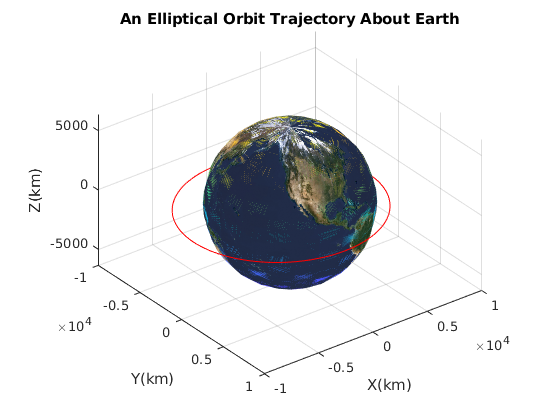

[x,y,z] = sphere; % create a sphere
Cord = [0 0 0 Body_Radius]; % use the equatorial radius of orbit body as a coordinate paramater
hold on;
Obj = surf(x*Cord(1,4),y*Cord(1,4),z*Cord(1,4)); % create a surface plot unique to the equatorial radius
set(Obj,'edgecolor','none');
daspect([1 1 1]); % set the aspect ratio
warp(x*Cord(1,4),y*Cord(1,4),z*Cord(1,4),map);
hold off;

**At last, we have a beautiful three-dimensional representation of a propagated orbit!**

## **State Changes Over Time:**

I would like to see how the orbit states change over the simulation time. I will plot each state verses time using the `subplot` feature.

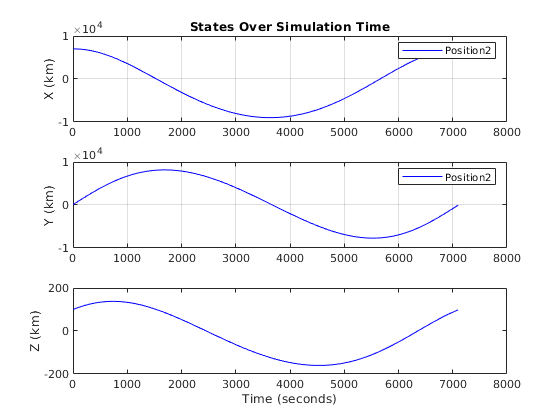

% using subplot, plot each position over time
% plot position in blue and velocity in red
figure;
subplot(311);
plot(tspan,States_X,'b');
title('States Over Simulation Time');
ylabel('X (km)')
legend('Position2');
grid on;
subplot(312);
plot(tspan,States_Y,'b');
ylabel('Y (km)')
legend('Position2');
grid on;
subplot(313);
plot(tspan,States_Z,'b');
ylabel('Z (km)')
xlabel('Time (seconds)')

legend('Position2');

Error using legend (line 273)
Mismatched number of name-value pair arguments. Specify a property value for each property name.

grid on;
% using subplot, plot each velocity over time
% plot position in blue and velocity in red
figure;
subplot(311);
plot(tspan,States_Xdot,'r');
title('States Over Simulation Time');
ylabel('X (km/s)')
legend('Velocity');
grid on;
subplot(312);
plot(tspan,States_Ydot,'r');
ylabel('Y (km/s)')
legend('Velocity');
grid on;
subplot(313);
plot(tspan,States_Zdot,'r');
ylabel('Z (km/s)')
xlabel('Time (seconds)')
legend('Velocity');
grid on;

## Perturbed VS. Unperturbed Comparison Plot:

If each perturbed and unperturbed orbit propagators ran, then we are able to compare the data. We will want to check for this.

% check to see if the variables in the workspace exist
if exist('Unperturbed_States','var') && exist('Perturbed_States','var')
    % Separate States
    Unperturbed_X_States = Unperturbed_States(:,1); Unperturbed_Y_States = Unperturbed_States(:,2); Unperturbed_Z_States = Unperturbed_States(:,3);
    Perturbed_X_States = Perturbed_States(:,1); Perturbed_Y_States = Perturbed_States(:,2); Perturbed_Z_States = Perturbed_States(:,3);
    % plot the trajectories
    figure;
    plot3(Unperturbed_X_States,Unperturbed_Y_States,Unperturbed_Z_States,'k'); % unperturbed states
    hold on;
    plot3(Perturbed_X_States,Perturbed_Y_States,Perturbed_Z_States,'-r'); % perturbed states
    title_form = sprintf('%s Trajectory About %s Comparison Plot',Orbit,Body); % make the title unique to the orbit body and conic section
    title(title_form);
    grid on;
    xlabel('X(km)');
    ylabel('Y(km)');
    zlabel('Z(km)');
    hold off;
    % Create the sphere
    [x,y,z] = sphere; % create a sphere
    Cord = [0 0 0 Body_Radius]; % use the equatorial radius of orbit body as a coordinate paramater
    hold on;
    Obj = surf(x*Cord(1,4),y*Cord(1,4),z*Cord(1,4)); % create a surface plot unique to the equatorial radius
    set(Obj,'FaceColor',[0 0.2 0.5], ...
          'FaceAlpha',0.8,'FaceLighting','gouraud','EdgeColor','none') % make the object pretty
    daspect([1 1 1]); % set the aspect ratio
    hold off;
end

# Functions:

## `Get_TOF():`

Create the function `Get_TOF`. The time of flight is calculated differently for each conic section orbit trajectory. To distiguish between conic sections, use the value of the eccentricity ($e$) to determine the appropriate method of calculating the time of flight ($T$).

function [T,Orbit] = Get_TOF(a,u,e,Body_Mass,Dist_to_Sun,Norbits)
% This function will input various orbital parameters and determine the spacecraft time of flight as well as the
% conic section of the trajectory

% INPUT - a = semimajor axis (km)
        % u = gravitational parameter
        % e = eccentricity
        % Body_Mass = Mass of the orbital body (kg)
        % Dist_to_Sun = The distance from the Sun (km) at which the orbital body orbits in the heliocentric frame
        
% OUTPUT - T = Time of flight of the spacecraft (sec)
         % Orbit = Conic section of the orbit trajectory (string type)

Should the value of $e$ be on the interval (0,1], then the conic section orbit trajectory will be either circular or elliptical. Calculate the orbit period using the method defined before:


$$T=2\pi n\sqrt{\frac{a^3 }{\mu }}$$


    if e < 1 && e >= 0 % if the orbit is circular or elliptical (we know by the value of eccentricity [0.0 - 1.0])
        T = 2*pi*Norbits*sqrt(a^3/u); % sec
        if e == 0
            Orbit = 'A Circular Orbit'; % orbit is circular
        else
            Orbit = 'An Elliptical Orbit'; % orbit is elliptical
        end
        

Should the value of $e$ be on the interval [1,$\infty$), then the conic section orbit trajectory will be hyperbolic. This is also known as a flyby orbit. It is safe to say that within the orbital body sphere of influence (SOI), the orbit body will be the dominant source of trajectory influence on the spacecraft, thus we would want to model the trajectory of the spacecraft the moment at which it enters the orbit body SOI to the moment at which it exits the SOI. First, we must calculate the SOI radius ($R_{\mathrm{soi}}$) using the following formula:

$R_{\mathrm{soi}} =R_{\mathrm{sun}} {\left(\frac{M_{\mathrm{body}} }{M_{\odot } }\right)}^{\frac{2}{5}}$    where $M_{\odot } =\mathrm{mass}\;\mathrm{of}\;\mathrm{the}\;\mathrm{Sun}$

    elseif e > 1 % if the orbit is hyperbolic (we know by the value of eccentricity [e>1])
        % Find the sphere of influence in relation to sun
        M_sun = 1.989e30; % Mass of the Sun in kg 
        R_soi = Dist_to_Sun*(Body_Mass/M_sun)^(2/5); % calculate the sphere of influence radius of the orbit body in km
        

We want to know the true anomaly ($\theta$) at which the spacecraft enters the SOI. We simply set the distance magnitude $R=R_{\mathrm{soi}}$ and we can determine $\theta \left(R\right)$ by:


$$R\left(\theta \right)=\frac{a\left(1-e^2 \right)}{1+\mathit{ecos}\left(\theta \right)}$$



$$\theta \left(R\right)={\mathrm{cos}}^{-1} \left(\frac{\frac{a\left(1-e^2 \right)}{R}-1}{e}\right)$$


        % find true anomaly at the edge of the sphere of influence
        R_mag = R_soi; % Distance magnitude is equal to the sphere of influence radius
        theta = acos(((a*(1-e^2)/R_mag)-1)/e); % using geometry, find the true anomaly at which the spacecraft enters the sphere of influence in radians
        

Using the true anomaly determined, we can determine the [hyperbolic anomaly](http://www.bogan.ca/orbits/kepler/orbteqtn.html) $F$ by:


$$F=2\mathrm{tanh}\left(\sqrt{\frac{e-1}{e+1}}\right)\mathrm{tan}\left(\frac{\theta }{2}\right)$$


        % find hyperbolic anomaly F
        F = 2*atanh(sqrt((e-1)/(e+1))*tan(theta/2)); % using geometry, find the hyperbolic anomaly from the true anomaly in radians
        

Finally, the time of flight ($T$) is found using the hyperbolic anomaly ($F$) by:


$$T=\sqrt{\frac{-a^3 }{\mu }}\left(\mathit{esin}\left(F\right)-F\right)$$


        % find time of flight out to edge of sphere of influence
        T = sqrt((-a)^3/u)*(e*sinh(F) - F); % from periapsis to the edge of the sphere of influence
        Orbit = 'A Hyperbolic Orbit'; % orbit is hyperbolic
        

Should the value of $e=1$, then the conic section orbit trajectory will be parabolic. A similar  approach is used from the case of a hyperbolic orbit trajectory.

    elseif e == 1 % if the orbit is parabolic (we know by the value of eccentricity [e=1])
        % Find the sphere of influence in relation to sun
        M_sun = 1.989e30; % Mass of the Sun in kg  
        R_soi = Dist_to_Sun*(Body_Mass/M_sun)^(2/5)*a; % calculate the sphere of influence radius of the orbit body in km
        
        % find true anomaly at the sphere of influence
        R_mag = R_soi; % Distance magnitude is equal to the sphere of influence radius
        theta = acos(((a*(1-e^2)/R_mag)-1)/e); % using geometry, find the true anomaly at which the spacecraft enters the sphere of influence in radians
        

Where this method differes from the hyperbolic case, we will want to find the [parabolic anomaly](http://www.bogan.ca/orbits/kepler/orbteqtn.html) ($D$) and use Barker's equation to determine the time of flight. $D$ and $T$ are determined by:


$$D=\mathrm{tan}\left(\frac{\theta }{2}\right)$$



$$T=\sqrt{2\frac{{a\left(1-e^2 \right)}^3 }{\mu }}\left(D+\frac{D^3 }{3}\right)$$


        % find parabolic anomaly D using Barker's equation
        D = tan(theta/2); % using geometry, find the parabolic anomaly from the true anomaly in radians
        % find time of flight from periapsis out to edge of sphere of influence
        T = sqrt(2*(a*(1-e^2))^3/u)*(D + D^3/3); % from periapsis to the edge of the sphere of influence
        Orbit = 'A Parabolic Orbit'; % orbit is parabolic
        

Should the chance that the eccentricity is complex or negative, then no calculation of the time of flight is possible and an error message is summoned. Data will need to be reentered.

    else
        % should the there be an error in calculation and somehow the value of eccentricity is negative, throw an error message
        T = 0; % in this case there will be no time of flight
        Orbit = 'No orbit'; % no orbit
        msgbox('Negative or complex eccentricity... Reenter data!','Data Error'); % error message
    end
end

## `Get_Disturbance():`

Create a function Get_Disturbance to obtain the disturbance acceleration to the perturbed orbit in Cartesian coordinates using Legendre polynomial expansion(1). I will utilize the Symbolic Math Toolbox to form a symbolic expression that represents the disturbance acceleration $\vec{A_d }$ at any specified zonal harmonic coefficient number $K$. In spherical coordinates, the gravitational potential $\Phi \left(r,\theta \right)$ due to spherical oblateness is:

$\Phi \left(r,\theta \right)=\frac{\mu }{r}\sum_{k=1}^{\infty } J_k \left(\frac{R}{r}\right)P_k \mathrm{cos}\left(\phi \right)$  where $P_k$ $\textrm{is}\;\textrm{a}\;\textrm{Legendre}\;\textrm{polynomial}$

function [A_d_Expression,J] = Get_Disturbance(K,u_param,r,r_e,phi,k,a,x,y,z)
% INPUT = all symbolic variables
% OUTPUT = Symbolic expression in Cartesian coordinates for disturbance acceleration, symbolic J terms
    J = sym('J',[1,K]); % create J according to polynomial expansion coefficient, J1,J2, or J3,... 

Our Legendre polynomials $P_k$ will be calculated and then used to obtain the disturbance acceleration $\vec{A_d }$. $P_k$ is found by:

$P_k =\frac{1}{2^k k!}\frac{\textrm{d}}{\textrm{d}x}{\left(x^2 -1\right)}^k$    where $k=1,2,3\ldotp \ldotp \ldotp$

    % Setup expression for Legendre Polynomials
    f = (a^2 - 1)^K;
    PK = (1/(2^(K)*factorial(K)))*diff(f,a,K);

We will specify the eigenfunction $\mathrm{cos}\left(\phi \right)$

    % substitute eigenfunction
    a = cos(phi);   
    % substitute for PK
    PK = subs(PK);    

We must now expand the infinite series from $k=1:K$

    % g expression from infinite series   
    gK = J(K)*(r_e/r)^K*PK;
    gK = subs(gK);
    UK = -(u_param/r)*symsum(gK,k,K,K);  

We must now take the negative gradient of the potential to determine the disturbance acceleration.


$$\vec{A_d } \left(r,\theta \right)=-\nabla \Phi \left(r,\theta \right)$$


  We may then convert the differential equation into Cartesian coordinates(1), yielding a symbolic expression for $\vec{A_d } \left(x,y,z\right)$.

    % Take the negative gradient
    A_d = -[diff(UK,r);diff(UK,phi)];
    phi = acos(z/(sqrt(x^2 + y^2 + z^2)));
    A_d = subs(A_d);
    dPhi = [diff(phi,x);diff(phi,y);diff(phi,z)];
    % cartesian conversion
    A_d_Expression = [A_d(1)*x/r + A_d(2)*dPhi(1)
                  A_d(1)*y/r + A_d(2)*dPhi(2)
                  A_d(1)*z/r + A_d(2)*dPhi(3)];
    A_d_Expression = subs(A_d_Expression,x^2 + y^2 + z^2,r^2);
end

## `OrbitState():`

Create the function `OrbitState to integrate the states over the determined time of flight. Throughout each step of the integration, a new distance magnitude (`$r_{\mathrm{new}}$) will be defined from the newly integrated position state vectors. Depending on our flag, we will choose to find the disturbance acceleration, or choose to set it to zero. Regardless, the output is the states matrix composing the position and velocity of the spacecraft at each point in time along the orbit.

function [State] = OrbitState(t,S,u,K,Body_Radius,J_num,flag)
    % find new position magnitude at each time step
    r_new = norm(S(1:3));
    % verify to perturb the orbit or not
    switch flag
        case 1
            % Initialize symbolic variables
            syms u_param r r_e phi k a x y z;
            A_d_old = 0; % initialize old value for disturbance acceleration
            % obtain A_d expressions 1:K
            for i=1:K
                [A_d_Expression,J] = Get_Disturbance(i,u_param,r,r_e,phi,k,a,x,y,z); % call the Get_Disturbance() function
                A_d_Expression = A_d_Expression + A_d_old; % add the previous value to the new value
                A_d_old = A_d_Expression; % previous value, becomes new value
            end            
            % substitute constant numerical values
            A_d_Expression = subs(A_d_Expression,r_e,Body_Radius); % sub for equatorial radius
            A_d_Expression = subs(A_d_Expression,u_param,u); % sub for gravitational parameter
            % substitute numerical values which are not constant into the expression
            A_d_Expression = subs(A_d_Expression,x,S(1)); % sub for x
            A_d_Expression = subs(A_d_Expression,y,S(2)); % sub for y
            A_d_Expression = subs(A_d_Expression,z,S(3)); % sub for z
            A_d_Expression = subs(A_d_Expression,r,r_new); % sub for r magnitude
            for i=1:K
                A_d_Expression = subs(A_d_Expression,J(1,i),J_num(i)); % how i do this?
            end
            A_d = double(vpa(A_d_Expression,6)); % simplify numerical values out to 6 sigfigs
            
        otherwise
            A_d = [0.0;0.0;0.0]; % set disturbance acceleration to zero
    end

Build the state-space representation model for the orbit equation.

    % Output State from orbital state-space form
    State = [S(4)
             S(5)
             S(6)
             (-u/r_new^3)*S(1) + A_d(1)
             (-u/r_new^3)*S(2) + A_d(2)
             (-u/r_new^3)*S(3) + A_d(3)];
end

# Title References:

- Battin, R. H., “Patched-Conic Orbits and Perturbation Methods” An Introduction to the Mathematics and Methods of Astrodynamics, American Institute of Aeronautics and Astronautics, Inc., Reston, VA, 1999, pp. 437-442.

- Curtis, H. D., “Introduction to Orbit Perturbations,” Orbital Mechanics for Engineering Students, 3rd ed., Butterworth-Heinemann, Oxford, UK, 2013, pp. 656-666.

- Williams, D. R, “Planetary Fact Sheet – Metric”, NASA Goddard Space Flight Center, NASA, MD, 2017, [https://nssdc.gsfc.nasa.gov/planetary/factsheet/](https://nssdc.gsfc.nasa.gov/planetary/factsheet/)

- Vallado, D. A., McClain, W. D, “Special Perturbation Techniques” Fundamentals of Astrodynamics and Applications, 2nd ed., Kluwer Academic Publishers Group, The Netherlands, 2004, pp. 511-546.